Plot the probability density function of the random variables and determine the mean and variance. The pdfs should be as follows:

`§` Exponential

`§` Bernoulli

`§` Binomial

`§` Geometric

`§` Normal

`§` Rayleigh

`§` Lognormal

`Step-1: Random Number Generation[0 to 1].`

clc
clear all
L_limit=0

L_limit = 0

U_limit=1

U_limit = 1

total=1000

total = 1000

R=L_limit+(U_limit-L_limit)*rand(total,1)  %Raw function to generate RV

R =     0.1612
    0.8227
    0.4010
    0.0447
    0.7845
    0.3258
    0.3312
    0.0756
    0.5072
    0.2685


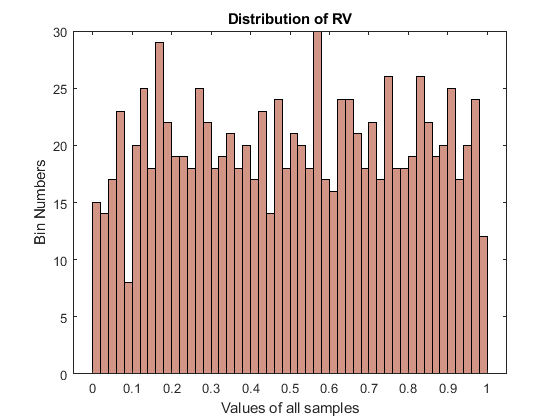

X =   Histogram with properties:

             Data: [1000×1 double]
           Values: [15 14 17 23 8 20 25 18 29 22 19 19 18 25 22 18 19 21 18 20 17 23 14 24 18 21 20 18 30 17 16 24 24 21 18 22 17 26 18 18 19 26 22 19 20 25 17 20 24 12]
          NumBins: 50
         BinEdges: [1×51 double]
         BinWidth: 0.0200
        BinLimits: [0 1]
    Normalization: 'count'
        FaceColor: [0.7000 0.3000 0.2000]
        EdgeColor: [0 0 0]

  Show all properties


Bin=50;
X=histogram(R,Bin);
xlabel('Values of all samples');
ylabel('Bin Numbers');
title('Distribution of RV') 
X.FaceColor = [.7 .3 .2]


m_1 = 0;
for count_1=1:total
    m_1=m_1+R(count_1);
end

Mean_R=(m_1/total)  %Raw code of Mean

Mean_R = 0.5077

Var_R=sum((R(1:end)-sum(R(1:end))./length(R)).^2)/(length(R)-1) %Raw code of Variance

Var_R = 0.0801



Mean_R1 =mean(R)  %Using Matlab function

Mean_R1 = 0.5077

Var_R1 =var(R)    %Using Matlab function

Var_R1 = 0.0801

Above function can generate 1000 random numbers between [0] to [1 ] with their Mean along with Variance and plot histogram with all samples and number of Bins.

***Step-2.1: Exponential conversion from RV(Random Variable).***

Now, we have to obtain an exponential random variable with mean 5 and representing the inter-arrival times of packets to a buffer.

From the formula of Exponential RV, we know: 

**FX(x) = 1-*****e*****^{-**$\lambda$***x}*****...(i)**

As we have taken random variables from 0 to 1 and PDF also operates between 0 to 1. We can consider to use our RV  as a function of PDF(Fx).

**FX(x) = R**

Now, if we put this value to equation (i), it will become:

   FX(x) = 1-*e*^{-$\lambda$**x*} 

  >    R = 1 - *e*^{-$\lambda$**x*} 

  >    *e*^{-$\lambda$**x*}  = 1 - R

  >   -$\lambda$**x* = log( 1- R)        % 'log' in both sides.

** x = -(1/**$\lambda$**)*log(1-R) **

Here, (1-R) = R   %Because it varies from 1 to 0.

Now, here mean is 5. So, 1/Lamda =5.

# **x = -(1/0.2)*log(R) **

mean_x=5;
x = -((mean_x)*log(R))

x =     0.5047
    0.3043
    1.1000
    7.0932
    0.1232
    5.7406
    1.0364
    1.8018
    6.5568
    2.6417


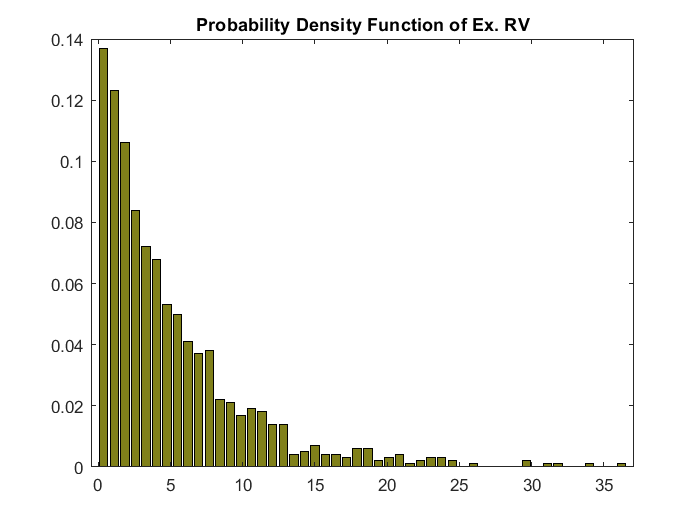

l_1 =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0.5000 0.5000 0.1000]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1×50 double]
        YData: [1×50 double]

  Show all properties


Bin=50;
%x1=x/1000;
[y1,y2]=hist(x,Bin);     %Histogram plot of PDF.
l_1=bar(y2,y1/1000);    %Normalizing y axis.
%x2=histogram(x1,Bin)
title('Probability Density Function of Ex. RV')
l_1.FaceColor = [.5 0.5 .1]

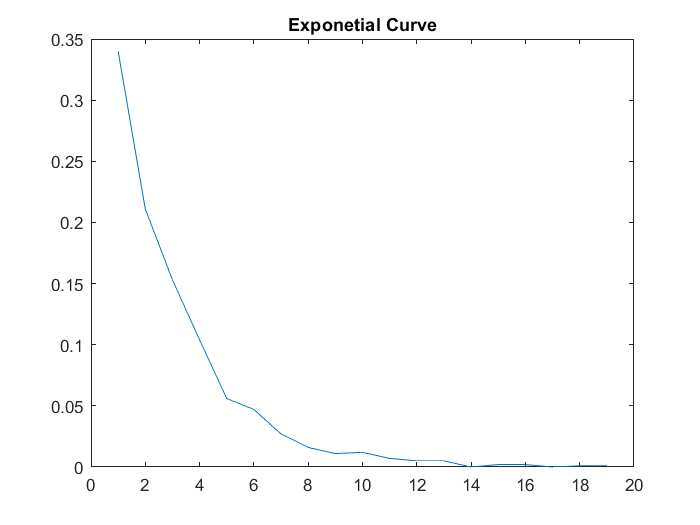

E=(histcounts(x))/total;
plot(E)
title('Exponetial Curve')


m= 0;
for count=1:total
    m=m+x(count);
end
Mean_X=(m/total)  %Raw code of Mean

Mean_X = 5.0056

Var_X=sum((x(1:end)-sum(x(1:end))./length(x)).^2)/(length(x)-1) %Raw code of Variance

Var_X = 26.6879



Mean_X1=mean(x)    %%Mean of the function

Mean_X1 = 5.0056

Var_X1=var(x)     %%Variance of the function

Var_X1 = 26.6879

Now, we have calculated Mean and Variance of 1000 exponential random variables. 

We got Mean ≈ 5 

From the formula, **E[X] =1/**$\lambda$**= 5**

So, Both are almost simiar.

And , We got Variance ≈25

From the formula, **E[X]^2 =1/(**$\lambda$**)^2= 25**

So, It's also simiar to our calculated value.

***Step-2.2: Random numbers to Bernoulli conversion***

A Bernoulli experiment includes a test once and noting while a experiment is conducting.

 ''Success'' or ''Failure'' these are two possible outcome for a bernoulli random variable experiment.

 So, for an event , let's declare 's' as probability of success.

 **if an event's probability is more than p then it is success , else failure.**

** if Event > s then 0 otherwise 1**

Bernoulli PMF,

P(X=x)=p^k(1-p)^(1-k)   Here: p = s

Now, if s=0.5,

Random numbers to Bernoulli conversion given below

s=0.5;
L_limit=0

L_limit = 0

U_limit=1

U_limit = 1

total=1000

total = 1000

R=L_limit+(U_limit-L_limit)*rand(total,1)  %Raw function to generate RV

R =     0.8147
    0.9058
    0.1270
    0.9134
    0.6324
    0.0975
    0.2785
    0.5469
    0.9575
    0.9649


Bin=2

Bin = 2

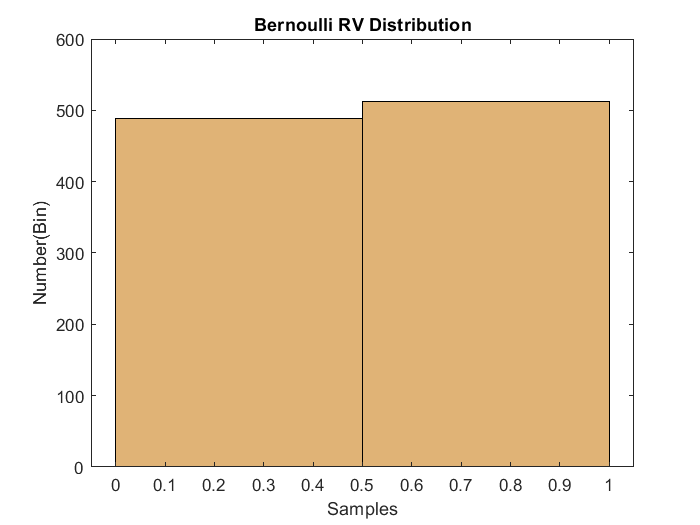

Brv=(R<=s);
Brv;
B=histogram(Brv,Bin);
title('Bernoulli RV Distribution');
xlabel('Samples');
ylabel('Number(Bin)');
B.FaceColor = [0.8 .5 .1];

**Mean and Variance **

m= 0;
for count=1:total
    m=m+Brv(count);
end
Mean_RawBrv=(m/total)  %Raw code of Mean

Mean_RawBrv = 0.5120

Var_RawBrv=sum((Brv(1:end)-sum(Brv(1:end))./length(Brv)).^2)/(length(Brv)-1) %Raw code of Variance

Var_RawBrv = 0.2501


Mean_Brv =mean(Brv)  %Mean Using Matlab function

Mean_Brv = 0.5120

Var_Brv =var(Brv)    %Variance Using Matlab function

Var_Brv = 0.2501

We got Mean ≈ 0.5 from the MATLAB funcion. Let's calculate using formula. 's' as probability of success.

***E[X]= s =0.5***

Furthermore, We got Variance approx ≈ 0.25, Let's calculate using formula

**VAR[X] = s(1-s)= 0.25**

***Step-2.3: Random numbers to Binomial conversion***

we know from the formula,

 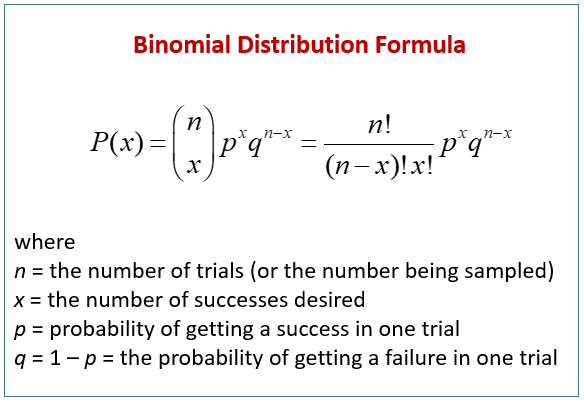

We can convert Bernoulli it into Binomial just by getting summations of all the bernoulli which are repeated(n Bernoulli). Now, let's declare 'p' as probability of success.

Let's consider p=0.5 and Number of experiment 1000 times.

n=1000;
p=0.5;
i=1;
Bi_rv = zeros(1,n);
while i<=n
    L_limit=0;
    U_limit=1;
    R=L_limit+(U_limit-L_limit)*rand(n,1);
    Brv=(R<=p);
    Bi_rv(i) = sum(Brv);
    i=i+1;
end
Bi_rv

Bi_rv =    500   519   521   480   509   498   498   500   481   517   523   523   487   480   509   523   514   484   488   531   480   482   510   489   493   483   485   476   506   528   496   497   503   506   510   503   496   489   491   509   502   491   498   521   513   510   509   518   505   500


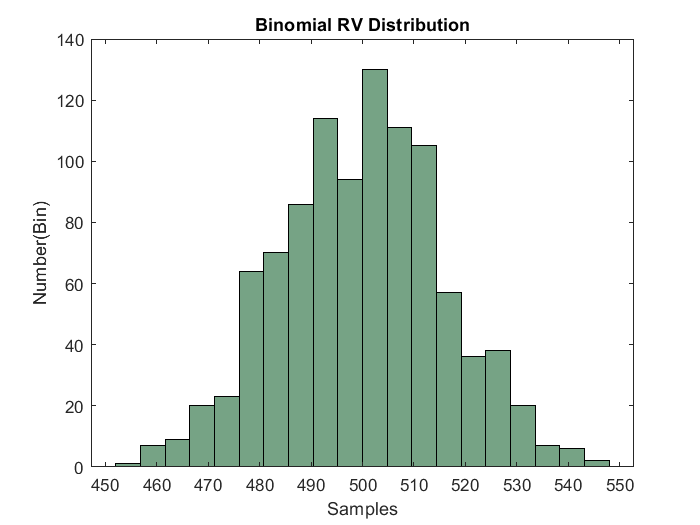

Bi=histogram(Bi_rv,20);
title('Binomial RV Distribution');
xlabel('Samples');
ylabel('Number(Bin)');
Bi.FaceColor = [0.1 0.4 0.2];

**Mean and Variance **

m= 0

m = 0

for count=1:total
    m=m+Bi_rv(count);
end
Mean_RawBirv=(m/total)  %Raw code of Mean

Mean_RawBirv = 499.6610

Var_RawBirv=sum((Bi_rv(1:end)-sum(Bi_rv(1:end))./length(Bi_rv)).^2)/(length(Bi_rv)-1) %Raw code of Variance

Var_RawBirv = 251.5136


Mean_Bi_rv =mean(Bi_rv)  %Mean Using Matlab function

Mean_Bi_rv = 499.6610

Var_Bi_rv =var(Bi_rv)    %Variance Using Matlab function

Var_Bi_rv = 251.5136

We got Mean ≈ 500 from the MATLAB funcion. Let's calculate using formula

***E[X]= np =500***

Furthermore, We got Variance approx ≈ 250, Let's calculate using formula

**VAR[X] = np(1-p)= 250**

***Step-2.4: Random numbers to Geometric Distribution***

In Geometric Distribution before first success the experiment is repeated.

Number of failure variable 'F' and 'p' as probability of success.

The probability of **F **is ,

**Before 1st success : (1-p)^F-1**

Let R be the uniform random variable from 0 to 1 representing probability of F,

Now, our Random variable 'R' in respect to failure.

               **R= (1-p)^F-1**

           ** > log( R )= log((1-p)^F-1)**

**            > (F-1)*log(1-p)= log( R )**

      **Hence, F = 1+ log( R )/log(1-p)**

**Calculating PDF untill 1st case:**

n=1000;
L_limit=0;
U_limit=1;
R=L_limit+(U_limit-L_limit)*rand(n,1);
p=0.2;

Grv=1+(log(R)/log(1-p));
Grv

Grv =     2.3204
   12.5981
    1.1923
    2.1960
    9.6150
   10.2260
    1.3486
    4.2673
    2.6646
    5.0250


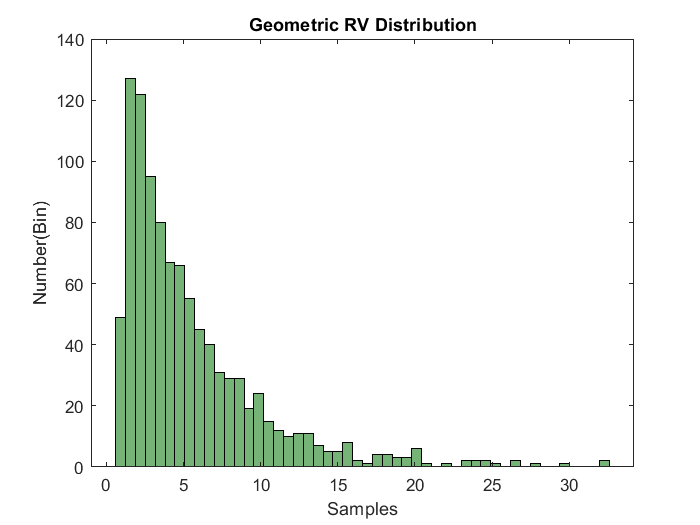


g=histogram(Grv,50);
g.FaceColor = [1 0.2 0];
title('Geometric RV Distribution');
xlabel('Samples');
ylabel('Number(Bin)');
g.FaceColor = [0.1 0.5 0.1];

**Mean and Variance **

m= 0;
for count=1:n
    m=m+Grv(count);
end
Mean_RawGrv=(m/n)  %Raw code of Mean

Mean_RawGrv = 5.4810

Var_RawGrv=sum((Grv(1:end)-sum(Grv(1:end))./length(Grv)).^2)/(length(Grv)-1) %Raw code of Variance

Var_RawGrv = 21.6032


Mean_Grv =mean(Grv)  %Mean Using Matlab function

Mean_Grv = 5.4810

Var_Grv =var(Grv)    %Variance Using Matlab function

Var_Grv = 21.6032

We got Mean ≈ 5 from the MATLAB funcion. Let's calculate using formula

***E[X]= 1/p =5***

Furthermore, We got Variance ≈ 20, Let's calculate using formula

**VAR[X] = (1-p)/p^2= 20**

**Calculating PDF before 1st case:**

n=1000;
L_limit=0;
U_limit=1;
R=L_limit+(U_limit-L_limit)*rand(n,1);
p=0.2;

Grv_1=log(R)/log(1-p);
Grv_1

Grv_1 =    10.2614
    0.7058
   17.8996
    0.5537
    4.3888
    0.6463
   10.0208
    2.0057
   19.5087
    4.9621


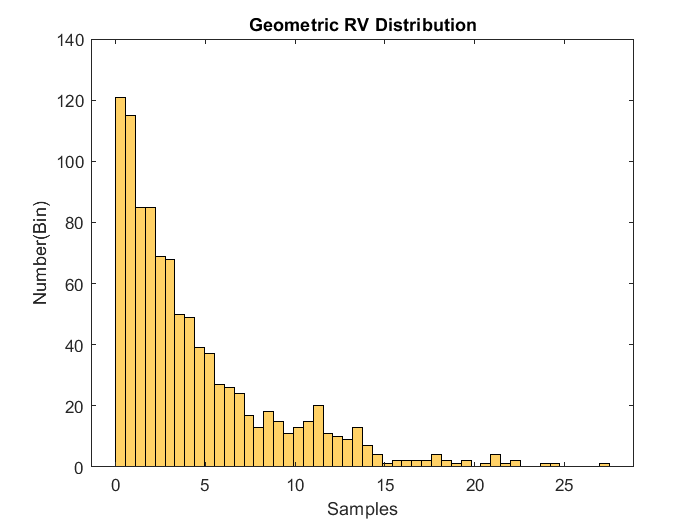


g1=histogram(Grv_1,50);
title('Geometric RV Distribution');
xlabel('Samples');
ylabel('Number(Bin)');
g1.FaceColor = [1 0.7 0];

**Mean and Variance **

m= 0;
for count=1:n
    m=m+Grv_1(count);
end
Mean_RawGrv_1=(m/n)  %Raw code of Mean

Mean_RawGrv_1 = 4.4299

Var_RawGrv_1=sum((Grv_1(1:end)-sum(Grv_1(1:end))./length(Grv_1)).^2)/(length(Grv_1)-1) %Raw code of Variance

Var_RawGrv_1 = 19.6366


Mean_Grv_1 =mean(Grv_1)  %Mean Using Matlab function

Mean_Grv_1 = 4.4299

Var_Grv_1 =var(Grv_1)    %Variance Using Matlab function

Var_Grv_1 = 19.6366

We got Mean ≈ 4 from the MATLAB funcion. Let's calculate using formula

***E[X]= (1-p)/p =4***

Furthermore, We got Variance ≈ 20, Let's calculate using formula

**VAR[X] = (1-p)/p^2= 20**

***Step-2.5: Random numbers to Normal Distribution***

In this case, we will take two random variables from a uniform distribution of [0,1]. Let the name of the variables R1 and R2. We will convert them to random normal distribution using below formula,

N1_rv= sqrt(-2*ln(R1)* Cos(2*pi*R1)

and

N2_rv= sqrt(-2*ln(R2)* Cos(2*pi*R2)

As, Normal distribution N(0,1), N1_rv and N2_rv  zero mean and variance 1.

Now, we will creat two random variables with 100 samples.

n=1000;
L_limit=0;
U_limit=1;
R1=L_limit+(U_limit-L_limit)*rand(n,1);
R2=L_limit+(U_limit-L_limit)*rand(n,1);

S=1; %small Sigma
M=0; %Mu
Bin=50;

N1 = sqrt(-2*log(R1)) .* cos(2*pi*R2);
Normal_rv1=N1*(S+M)

Normal_rv1 =    -0.0180
    0.5865
    1.0011
    1.3327
    1.9768
   -0.2879
    2.1827
    0.5299
    0.6141
    1.4873


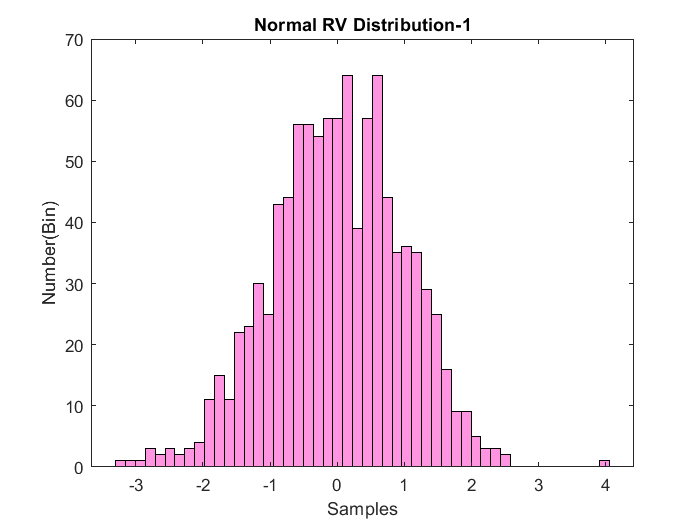

n1=histogram(Normal_rv1,Bin);
title('Normal RV Distribution-1');
xlabel('Samples');
ylabel('Number(Bin)');
n1.FaceColor = [1 0.3 0.8];


N2= sqrt(-2*log(R2)) .* sin(2*pi*R1);
Normal_rv2=N2*(S+M)

Normal_rv2 =    -1.3211
   -0.4086
   -1.7400
    1.9779
    0.1833
   -0.9422
    1.1088
   -0.5322
    1.3449
    1.3629


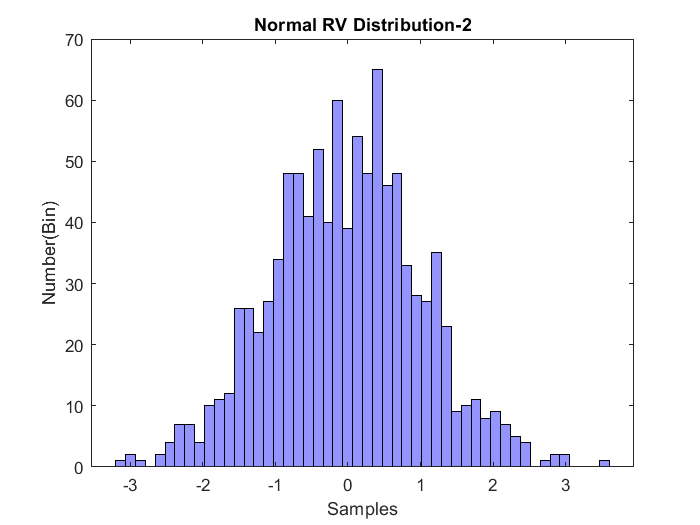

n2=histogram(Normal_rv2,Bin);
title('Normal RV Distribution-2');
xlabel('Samples');
ylabel('Number(Bin)');
n2.FaceColor = [0.3 0.3 1];

**Mean and Variance **

m= 0;
for count=1:n
    m=m+Normal_rv1(count);
end
Mean_RawNormal_rv1=(m/n)  %Raw code of Mean

Mean_RawNormal_rv1 = 0.0079

Var_RawNormal_rv1=sum((Normal_rv1(1:end)-sum(Normal_rv1(1:end))./length(Normal_rv1)).^2)/(length(Normal_rv1)-1) %Raw code of Variance

Var_RawNormal_rv1 = 0.9589


Mean_Normal_rv1 =mean(Normal_rv1)  %Mean Using Matlab function

Mean_Normal_rv1 = 0.0079

Var_Normal_rv1 =var(Normal_rv1)    %Variance Using Matlab function

Var_Normal_rv1 = 0.9589


m= 0;
for count=1:n
    m=m+Normal_rv2(count);
end
Mean_RawNormal_rv2=(m/n)  %Raw code of Mean

Mean_RawNormal_rv2 = -0.0254

Var_RawNormal_rv2=sum((Normal_rv2(1:end)-sum(Normal_rv2(1:end))./length(Normal_rv2)).^2)/(length(Normal_rv2)-1) %Raw code of Variance

Var_RawNormal_rv2 = 1.0559


Mean_Normal_rv2 =mean(Normal_rv2)  %Mean Using Matlab function

Mean_Normal_rv2 = -0.0254

Var_Normal_rv2 =var(Normal_rv2)    %Variance Using Matlab function

Var_Normal_rv2 = 1.0559

We got Mean ≈ 0 from the MATLAB funcion. Let's calculate using formula

***E[X]= Mu =0***

Furthermore, We got Variance ≈ 1, Let's calculate using formula

**VAR[X] = Sigma^2= 1**

***Step-2.6: Random numbers to Rayleigh***

${\displaystyle R={\sqrt {X^{2}+Y^{2}}}}$, this is Rayleigh distribution.

Here, X,Y tends to N(**Mu,Sigma**) . Bith are independent normal RV.

Let's consider Mu=0 and Sigma=1.

n=1000;
L_limit=0;
U_limit=1;
R1=L_limit+(U_limit-L_limit)*rand(n,1);
R2=L_limit+(U_limit-L_limit)*rand(n,1);

Bin=50;

N1 = sqrt(-2*log(R1)) .* cos(2*pi*R2);
N2= sqrt(-2*log(R1)) .* sin(2*pi*R2);

R_rv=sqrt(N1.^2 + N2.^2)

R_rv =     0.9182
    0.7339
    1.1992
    0.5848
    1.5897
    1.0043
    1.7645
    1.2699
    1.3980
    0.3460


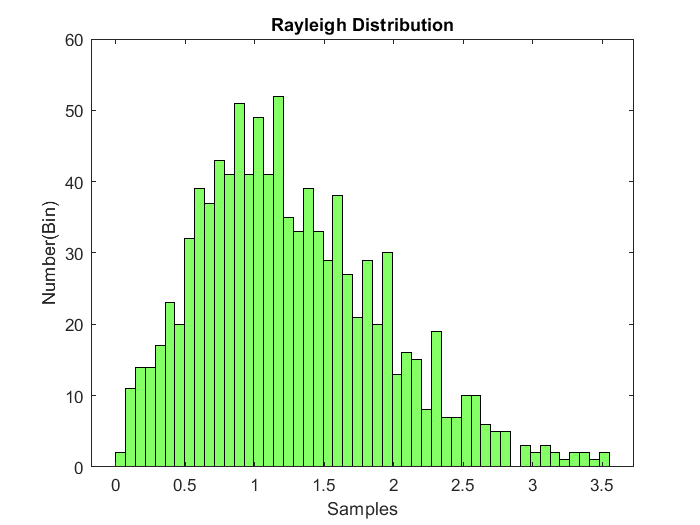


r=histogram(R_rv,Bin);
title('Rayleigh Distribution');
xlabel('Samples');
ylabel('Number(Bin)');
r.FaceColor = [.2 1 0];

**Mean and Variance **

m= 0;
for count=1:n
    m=m+R_rv(count);
end
Mean_RawR_rv=(m/n)  %Raw code of Mean

Mean_RawR_rv = 1.2664

Var_RawR_rv=sum((R_rv(1:end)-sum(R_rv(1:end))./length(R_rv)).^2)/(length(R_rv)-1) %Raw code of Variance

Var_RawR_rv = 0.4372


Mean_R_rv =mean(R_rv)  %Mean Using Matlab function

Mean_R_rv = 1.2664

Var_R_rv =var(R_rv)    %Variance Using Matlab function

Var_R_rv = 0.4372

We got Mean ≈ 1.2 from the MATLAB funcion. Let's calculate using formula

***E[X]= sigma*sqrt(pi/2) =1*sqrt(pi/2)=1.2***

Furthermore, We got Variance ≈ 0.4, Let's calculate using formula

**VAR[X] =(2- *****pi/2)*Sigma^2*****= (2- *****pi/2)*1^2=0.4***

***Step-2.7: Random numbers to Lognormal***

Lognormal RV has similarities with Normal distribution. Normal distribution is like bell curve and in Lognormal distribution there's right skew with bell curve where tail never goes to '0'.

we  can get lognormal distribution if we apply log function to normal distribution

Let, lognormal distribution = Ln

if 'N' is the normal distribution, then

N=log(Ln)

If we take exponential on both sides,

Ln=exp^(N)

Let's consider Mu=0 and Sigma=1.

n=1000;
L_limit=0;
U_limit=1;
R1=L_limit+(U_limit-L_limit)*rand(n,1);
R2=L_limit+(U_limit-L_limit)*rand(n,1);

S=0.5; %small Sigma
M=5; %Mu
Bin=50;

L = sqrt(-2*log(R1)) .* cos(2*pi*R2);
Normal_rv=L*S+M;

Lognormal_RV=exp(Normal_rv)

Lognormal_RV =   119.4188
  129.4886
  409.7770
  153.6059
  112.6885
   63.2798
   80.8746
  209.4124
  171.6596
  131.9476


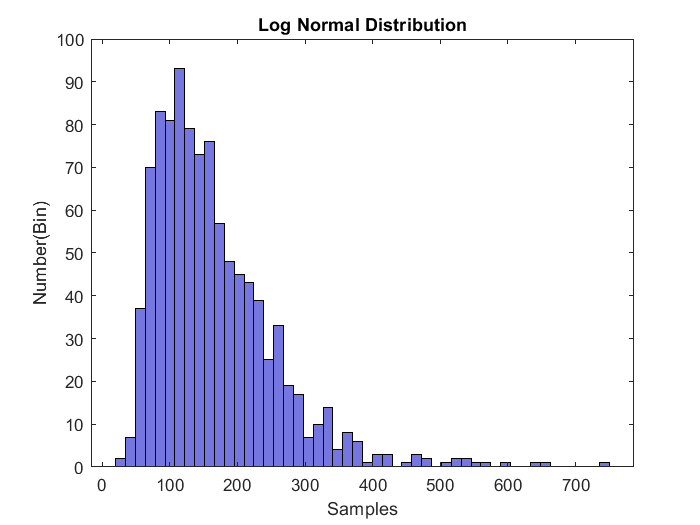


l=histogram(Lognormal_RV,Bin);
title('Log Normal Distribution');
xlabel('Samples');
ylabel('Number(Bin)');
l.FaceColor = [0.1 0.1 0.8];

**Mean and Variance **

m= 0;
for count=1:n
    m=m+Lognormal_RV(count);
end
Mean_RawLognormal_RV=(m/n)  %Raw code of Mean

Mean_RawLognormal_RV = 166.1797

Var_RawLognormal_RV=sum((Lognormal_RV(1:end)-sum(Lognormal_RV(1:end))./length(Lognormal_RV)).^2)/(length(Lognormal_RV)-1) %Raw code of Variance

Var_RawLognormal_RV = 8.2223e+03


Mean_Lognormal_RV =mean(Lognormal_RV)  %Mean Using Matlab function

Mean_Lognormal_RV = 166.1797

Var_Lognormal_RV =var(Lognormal_RV)    %Variance Using Matlab function

Var_Lognormal_RV = 8.2223e+03

We got Mean ≈ 166 from the MATLAB funcion. Let's calculate using formula

***E[X]= e^(Mu+.5*Sigma^2) =168***

Furthermore, We got Variance ≈ 8223, Let's calculate using formula

**VAR[X] =e^(2*Mu+Sigma^2)= 8033**

## `Discussion:`

The main objective of this project was converting random variables to different types of distribution such as Exponential, Bernoulli, Binomial, Geometric, Normal, Rayleigh, Lognormal. I have checked our calculated values with formulated values by comparing Mean and Variance to prove formulas of Textbook. Another property I notiched while doing this project, all RV(Random Variables) are deeply connected with one another. We can convert any of them using mathemetics and get the help from MATLAB.